# (a)

## PCL Height profile at 100GHz

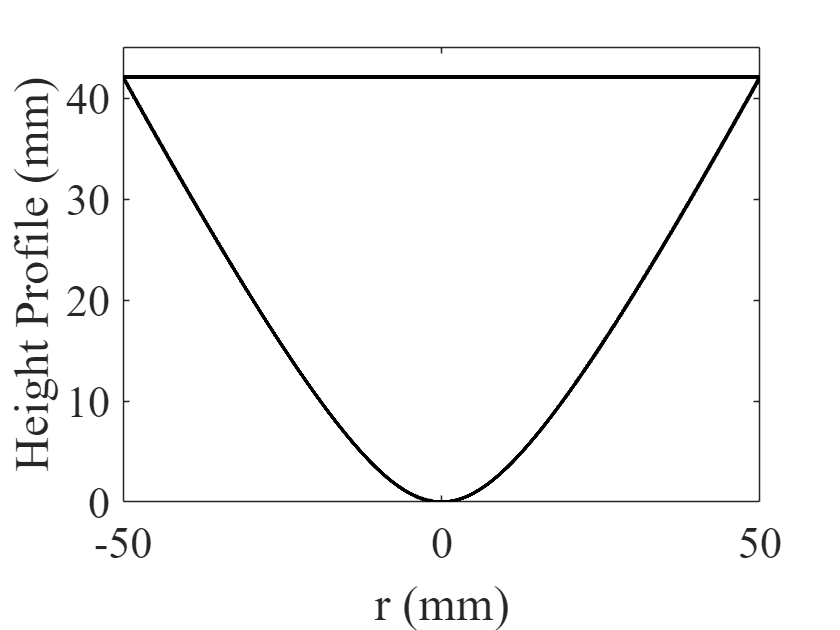

rg=11.9;
rft=400;
d=3000;
Dl=100;
lda0=3;
n=1.45;
w1=1.0*(2)*rg; %mm
w2=2*rft; %mm
alpha_opt=0.79;
%alpha_opt=0.79 is desired
L=52;% CST desired
TT=linspace(0,pi/2,4000000);
H1=(n-1)*L*sin(TT);
H2=(Dl/2)*(n*cos(TT)-1);
H3=abs(H2-H1);
[in1,in2]=min(H3);
theta0=rad2deg(TT(in2));
theta=linspace(0,deg2rad(theta0),2561);
% coll.profile
R=(n-1)*L./(n*cos(theta)-1);
hc=R.*cos(theta)-L;
r=R.*sin(theta);
rf=[-fliplr(r(2:end)),0,r(2:end)];
hcf=[fliplr(hc(2:end)),0,hc(2:end)];
figure
coe1=sqrt(1-exp(-2*(Dl/(2*rg))^2));
coe2=1/((n-1)*d);
coe3=(coe2/coe1)*rft;
F1=@(gm)coe3*sqrt(1-exp(-2*(gm/rg).^2));
F2=@(gm)coe2*(-1)*gm;
F3=@(gm)F1(gm)-F2(gm);% optimized function is considered
hb=zeros(1,length(r));
for i=1:length(r)
    Rp=r(i);
    hb(i)=integral(F3,0,Rp);
end

hbf=[fliplr(hb(2:end)),0,hb(2:end)];
hpcl_opt=alpha_opt*hb+hc;
hpcl=hb+hc;
hb_opt=alpha_opt*hb;
hpclf=[fliplr(hpcl(2:end)),0,hpcl(2:end)];
hpclf_opt=[fliplr(hpcl_opt(2:end)),0,hpcl_opt(2:end)];
% constf1=hcf(end)*ones(1,length(rf));
% constf2=hbf(end)*ones(1,length(rf));
constf3=hpclf(end)*ones(1,length(rf));
constf3_opt=hpclf_opt(end)*ones(1,length(rf));

figure
plot(rf,hpclf_opt,'k','LineWidth',2)
hold on
plot(rf,constf3_opt,'k','LineWidth',2)
hold on 
xlabel('r (mm)')
ylabel('Height Profile (mm)')
set(gca,'fontname','times new roman','fontsize',22)
ylim([0,constf3(1)])
xlim([-50,50])

## Output flat-top beam of PCL at 100GHz using:

## 1) Analytical method

## 2) IE MLFMM method

## 3) FEM (COMSOL)

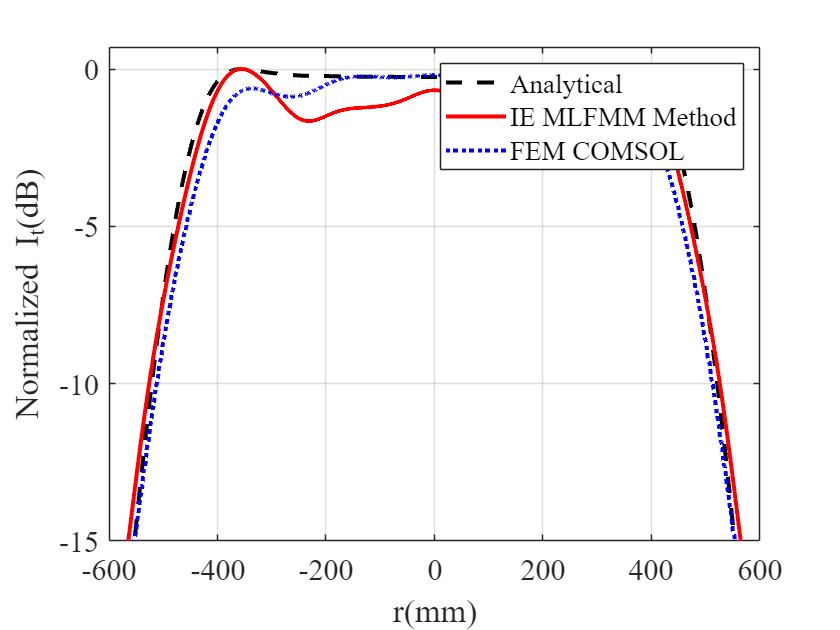

yc=linspace(-100,100,3000);
syms s xp x
S1=exp(-8*(s^2/80^2));
S=int(S1,-200/2,xp);
SD=int(S1,s,-200/2,200/2);
phi1=(2*pi)/(lda0*2000)*(700*((S/SD)-0.5)-xp);
phi2=int(phi1,xp,-200/2,x);
phi3=subs(phi2,x,yc);
phi_u0=double(phi3);
Einn_abs=exp(-4*(yc/80).^2);
[X,Eoutn_A]=SFT(Einn_abs,phi_u0,yc,lda0,2000+750,700);
Iout=abs(Eoutn_A).^2;
O2=load("PCL_E_field_opt=0.79_CST.txt");
ropt=O2(:,1)-900;
Iout_opt=(O2(:,2)/max(O2(:,2))).^2;
C1=load("PCL_opt0.79_COMSOL.txt");
rC1=C1(:,1)-800;
Iout_comsol=(C1(:,2)/max(C1(:,2))).^2;
Iout_comsol_s=smoothdata(Iout_comsol,'sgolay',25);
figure
plot(X,10*log10(Iout),'k--','linewidth',2)
hold on
plot(ropt,10*log10(Iout_opt),'r','LineWidth',2)
hold on
plot(rC1,10*log10(Iout_comsol_s),'b:','LineWidth',2)
xlabel('r(mm)')
ylabel('Normalized I_o_u_t(dB)')
legend('Analytical','IE MLFMM Method','FEM COMSOL')
grid
xlim([-600,600])
ylim([-15,0.7])
set(gca,'fontname','times new roman','fontsize',15)

# (b)

## PCL Height profile at 200GHz (alpha_opt=0 and d=4 m)

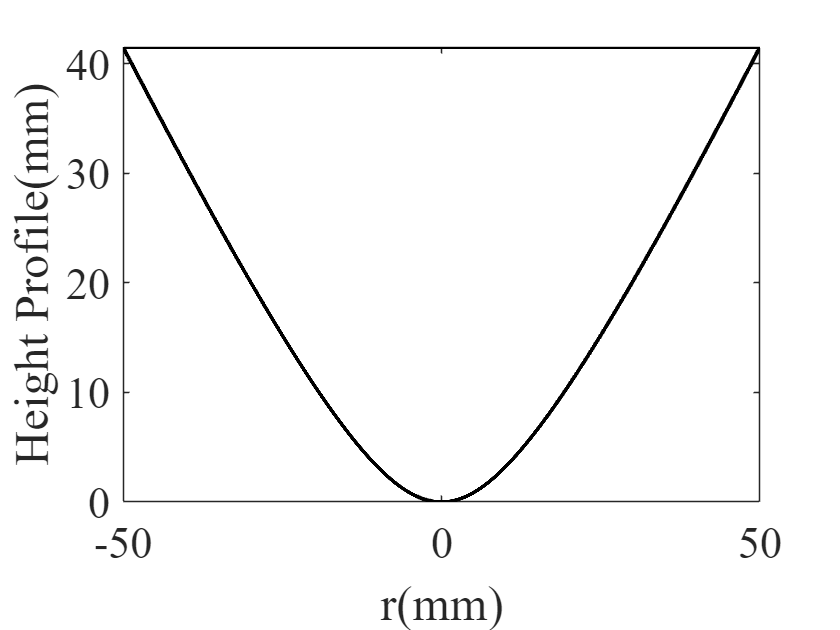

d2=4000;%mm
coe1=sqrt(1-exp(-2*(Dl/(2*rg))^2));
coe2=1/((n-1)*d2);
coe3=(coe2/coe1)*rft;
F1=@(gm)coe3*sqrt(1-exp(-2*(gm/rg).^2));
F2=@(gm)coe2*(-1)*gm;
F3=@(gm)F1(gm)-F2(gm);% optimized function is considered
hb2=zeros(1,length(r));
for i=1:length(r)
    Rp=r(i);
    hb2(i)=integral(F3,0,Rp);
end

hbf2=[fliplr(hb2(2:end)),0,hb2(2:end)];
hpcl_200GHz=hb2+hc;
hpclf_200GHz=[fliplr(hpcl_200GHz(2:end)),0,hpcl_200GHz(2:end)];
constf1=hcf(end)*ones(1,length(rf));
constf2=hbf2(end)*ones(1,length(rf));
constf3=hpclf_200GHz(end)*ones(1,length(rf));
figure
plot(rf,hpclf_200GHz,'k','LineWidth',2)
hold on
plot(rf,constf3,'k','LineWidth',2)
xlabel('r(mm)')
ylabel('Height Profile(mm)')
set(gca,'fontname','times new roman','fontsize',22)
ylim([0,constf3(1)])
xlim([-50,50])

## Output flat-top beam of PCL at 200GHz using:

## 1) Analytical method

## 2) IE MLFMM method

**3) FEM (COMSOL)**

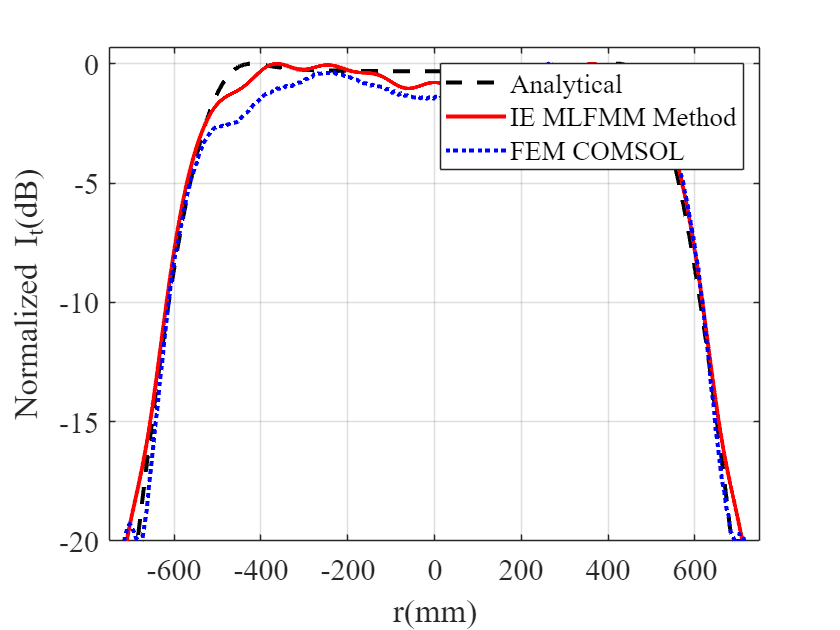

O5=load('PCL_absE_COMSOL_200GHz.txt');
O6=load('PCL_argE_COMSOL_200GHz.txt');
xd_200=O5(:,1)'-800;
E_abs_200G=O5(:,2)'/max(O5(:,2));
E_abs_200G=smoothdata(E_abs_200G,'sgolay',25);
E_arg_200G=unwrap(O6(:,2)');
E_arg_200G=smoothdata(E_arg_200G,'sgolay',25);
[Xc_200,Eoutn_FEM]=SFT(E_abs_200G,E_arg_200G,xd_200,lda0/2,6900,10000);
Iout_200_FEM=abs(Eoutn_FEM).^2;
[X_200,Eoutn_A_200]=SFT(Einn_abs,phi_u0,yc,lda0/2,5800+750,700);
Iout_200=abs(Eoutn_A_200).^2;
O4=load("PCL_200GHz_E_field_opt=0_CST.txt");
r200G=O4(:,1)-1000;
Iout_200G=(O4(:,2)/max(O4(:,2))).^2;
figure
plot(X_200,10*log10(Iout_200),'k--','linewidth',2)
hold on
plot(r200G,10*log10(Iout_200G),'r','LineWidth',2)
hold on
plot(Xc_200,10*log10(Iout_200_FEM),'b:','LineWidth',2)

xlabel('r(mm)')
ylabel('Normalized I_o_u_t(dB)')
legend('Analytical','IE MLFMM Method','FEM COMSOL')
grid
xlim([-750,750])
ylim([-20,0.7])

set(gca,'fontname','times new roman','fontsize',15)

# (c)

## CCL Height profile at 100GHz

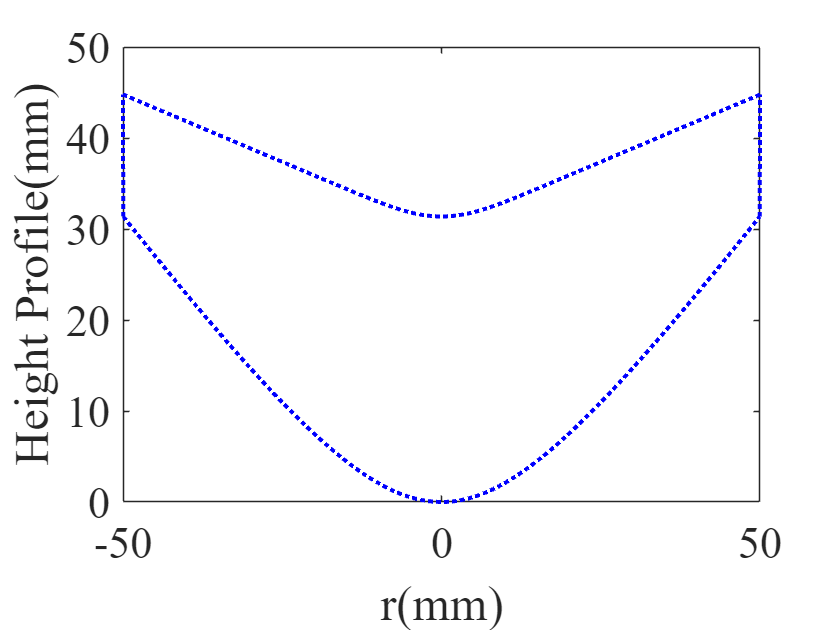

%CCL: Collimator
L_coll=50;
t=linspace(0,0.5507,2561);
x_coll=(sin(t)*(n-1)*L_coll)./(n*cos(t)-1);
y_coll=((cos(t)*(n-1)*L_coll)./(n*cos(t)-1))-L_coll;
x_coll=[-fliplr(x_coll(2:end)),0,x_coll(2:end)];
y_coll=[fliplr(y_coll(2:end)),0,y_coll(2:end)];
%CCL: Beam Shaper Profile
Profile_CCL_BS=load('CCL_BS_profile.txt')';
r_CCL=[-fliplr(Profile_CCL_BS(1,2:end)),0,(Profile_CCL_BS(1,2:end))];
BS_CCL=[fliplr(Profile_CCL_BS(2,2:end)),0,(Profile_CCL_BS(2,2:end))];
BS_CCL=BS_CCL+y_coll(end);

figure
plot(r_CCL,BS_CCL,'b:','LineWidth',2);
hold on
plot(x_coll,y_coll,'b:','LineWidth',2)
hold on
plot([x_coll(end),r_CCL(end)],[y_coll(end),BS_CCL(end)],'b:','LineWidth',2)
hold on
plot([x_coll(1),r_CCL(1)],[y_coll(1),BS_CCL(1)],'b:','LineWidth',2)
xlabel('r(mm)')
ylabel('Height Profile(mm)')
set(gca,'fontname','times new roman','fontsize',22)
% ylim([0,constf3(1)])
xlim([-50,50])

## Output flat-top beam of CCL at 100GHz using:

## 1) Analytical method

## 2) IE MLFMM method

## 3) FEM (COMSOL)

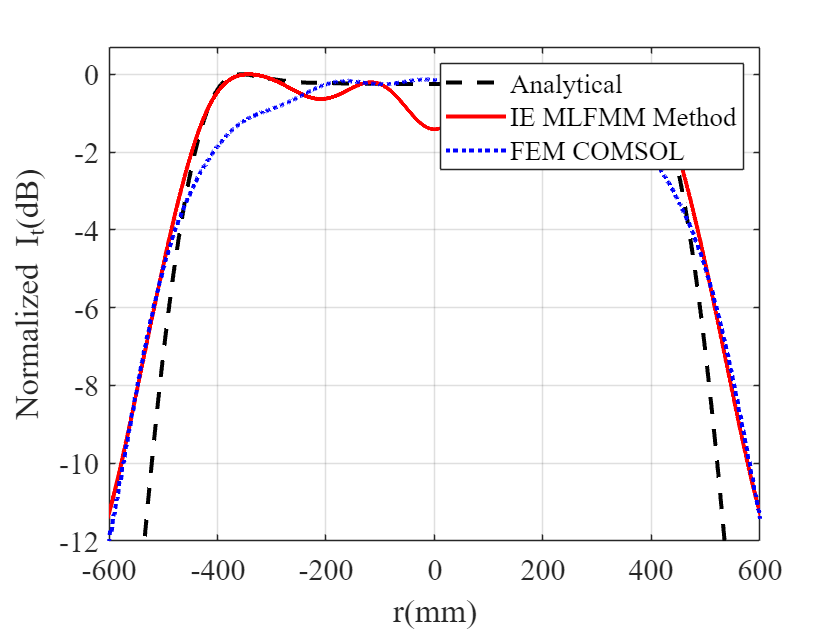

O3=load("CCL_E_field_CST.txt");
rccl=O3(:,1);
Iout_ccl=(O3(:,2)/max(O3(:,2))).^2;
C2=load("CCL_COMSOL.txt");
rC2=C2(:,1)-800;
Iout_comso2=(C2(:,2)/max(C2(:,2))).^2;
Iout_comsol_s2=smoothdata(Iout_comso2,'sgolay',25);
figure
plot(X,10*log10(Iout),'k--','linewidth',2)
hold on
plot(rccl,10*log10(Iout_ccl),'r','LineWidth',2)
hold on
plot(rC2,10*log10(Iout_comsol_s2),'b:','LineWidth',2)
xlabel('r(mm)')
ylabel('Normalized I_o_u_t(dB)')
legend('Analytical','IE MLFMM Method','FEM COMSOL')
grid
xlim([-600,600])
ylim([-12,0.7])
set(gca,'fontname','times new roman','fontsize',15)

# (d)

## PCL: 3D Output Beam (100GHz)

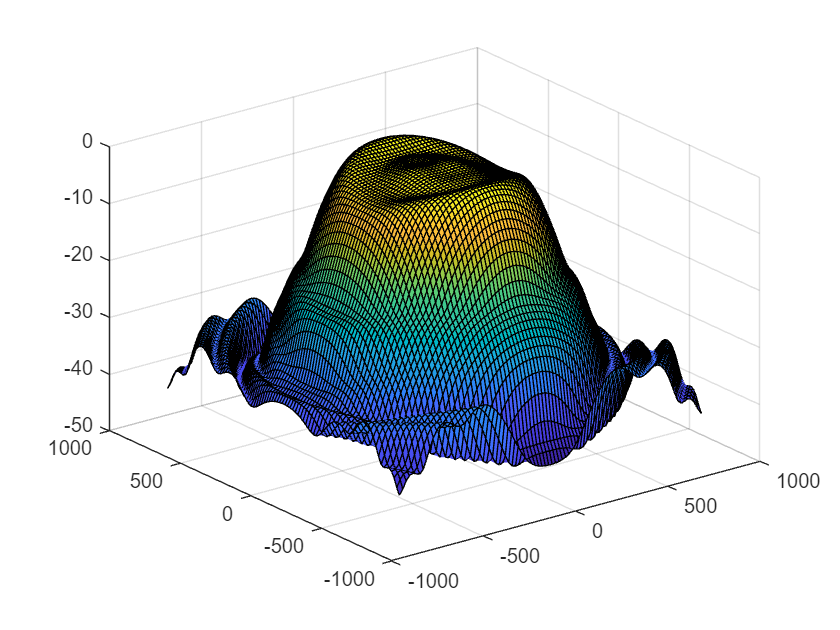

[X1,Y1,E3D_cal1]=Efieldcalculation("3D_output_field_PCL_100GHz.txt");
figure
surf(X1,Y1,20*log10(E3D_cal1/max(max(E3D_cal1))));

# (e)

## PCL: 3D Output Beam (200GHz)

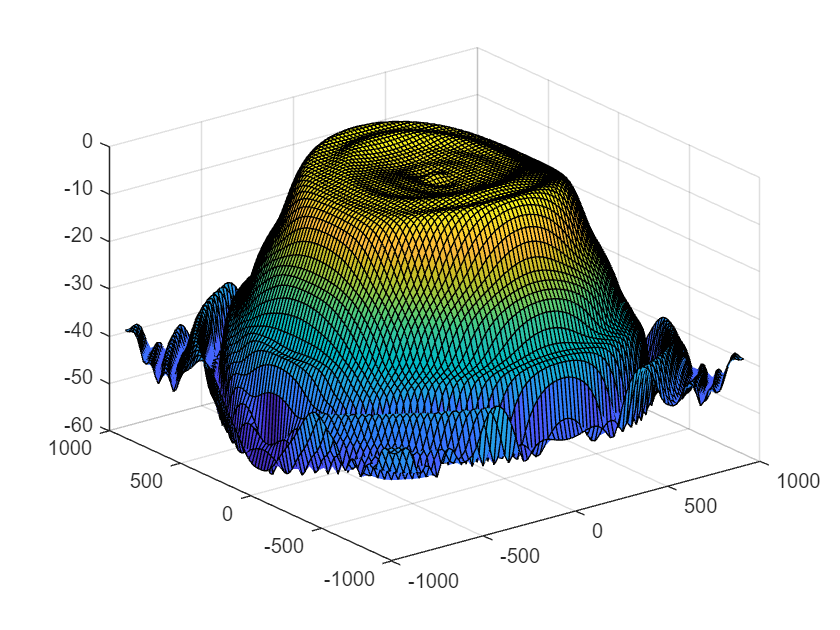

[X2,Y2,E3D_cal2]=Efieldcalculation("3D_output_field_PCL_200GHz.txt");
figure
surf(X2,Y2,20*log10(E3D_cal2/max(max(E3D_cal2))));

# (f)

## CCL: 3D Output Beam (100GHz)

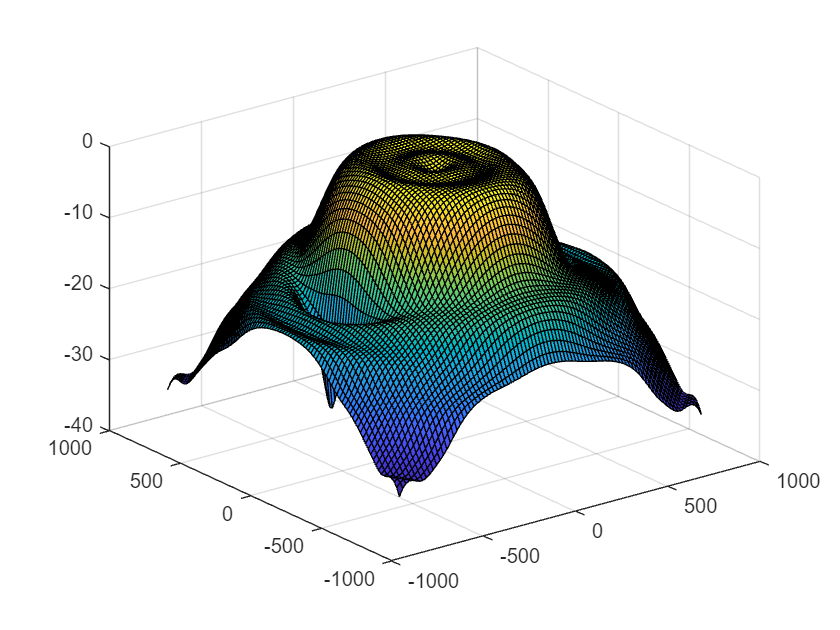

[X3,Y3,E3D_cal3]=Efieldcalculation("3D_output_field_CCL_100GHz.txt");
figure
surf(X3,Y3,20*log10(E3D_cal3/max(max(E3D_cal3))));

# Figure 5

## Sensitivity Analysis of CCL

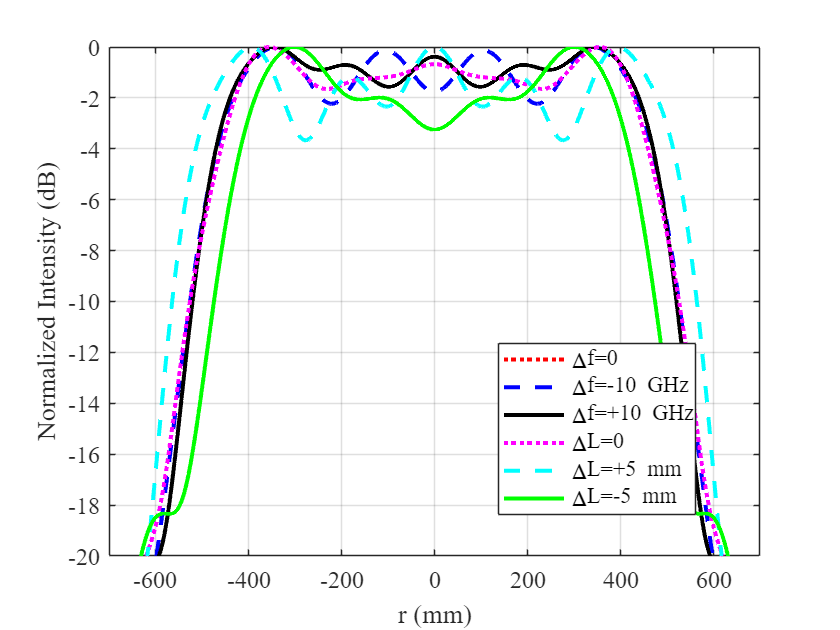

% =======================
% Frequency Curves
% =======================
F1=load("PCL_opt0.79_f90.txt");
F2=load("PCL_opt0.79_f110.txt");
xF1=F1(:,1)-900;
xF2=F2(:,1)-900;
IF1=20*log10(F1(:,2)/max(F1(:,2)));
IF2=20*log10(F2(:,2)/max(F2(:,2)));

% =======================
% Distance Curves
% =======================
D1=load("PCL_opt0.79_L47.txt");
D2=load("PCL_opt0.79_L57.txt");
xD1=D1(:,1)-900;
xD2=D2(:,1)-900;
ID1=20*log10(D1(:,2)/max(D1(:,2)));
ID2=20*log10(D2(:,2)/max(D2(:,2)));

% =======================
% Plot All in One Figure
% =======================
figure
% Frequency set
plot(ropt,10*log10(Iout_opt),'r:','LineWidth',2); hold on  % Δf=0
plot(xF1,IF1,'b--','LineWidth',2); hold on                % Δf=-10 GHz
plot(xF2,IF2,'k-','LineWidth',2); hold on                 % Δf=+10 GHz

% Distance set
plot(ropt,10*log10(Iout_opt),'m:','LineWidth',2); hold on  % ΔL=0
plot(xD2,ID2,'c--','LineWidth',2); hold on                % ΔL=+5 mm
plot(xD1,ID1,'g-','LineWidth',2);                         % ΔL=-5 mm

xlabel('r (mm)')
ylabel('Normalized Intensity (dB)')
legend({'\Deltaf=0','\Deltaf=-10 GHz','\Deltaf=+10 GHz',...
        '\DeltaL=0','\DeltaL=+5 mm','\DeltaL=-5 mm'},...
        'Location','best')
set(gca,'fontname','times new roman','fontsize',12)
xlim([-700,700])
ylim([-20,0])
grid on

## Efficiency Calculation

[X5,Y5,E3D_cal5]=Efieldcalculation("3D_Gaussian_outputplane.txt");
[X1,Y1,E3D_cal1]=Efieldcalculation("3D_output_field_PCL_100GHz.txt");
[X3,Y3,E3D_cal3]=Efieldcalculation("3D_output_field_CCL_100GHz.txt");
x1=linspace(-820,820,900);
y1=x1;
[X1q,Y1q]=meshgrid(x1,y1);
E3D_cal5q=interp2(X5,Y5,E3D_cal5,X1q,Y1q);
E3D_cal1q=interp2(X1,Y1,E3D_cal1,X1q,Y1q);
E3D_cal3q=interp2(X3,Y3,E3D_cal3,X1q,Y1q);
Ea_flat1=trapz(x1,E3D_cal1q,2);
Eb_flat1=trapz(y1,Ea_flat1);

Ea_Guas=trapz(x1,E3D_cal5q,2);
Eb_Guas=trapz(y1,Ea_Guas);

Ea_flat3=trapz(x1,E3D_cal3q,2);
Eb_flat3=trapz(y1,Ea_flat3);

Eff_PCL=(Eb_flat1/Eb_Guas)*100

Eff_PCL = 72.2834

Eff_CCL=(Eb_flat3/Eb_Guas)*100

Eff_CCL = 86.3592

## Spill-over Eff.

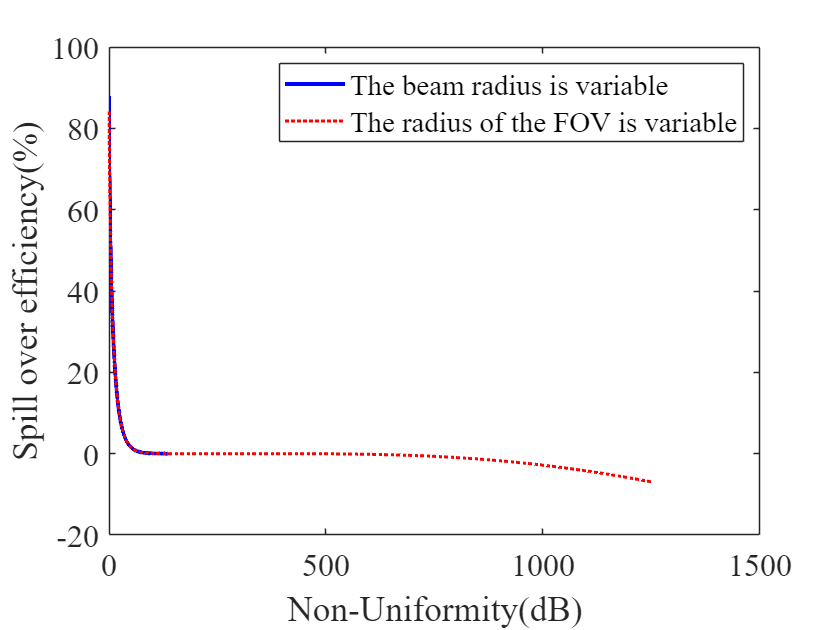

x0=3;
x0min=(1/1.975394)*x0;
x0max=(1/0.075871)*x0;
w0=linspace(x0min,x0max,4000);
nonu=exp(8*(x0./w0).^2);
nonudb=10*log10(nonu);
x=linspace(-0.5*x0,0.5*x0,4000);
y=linspace(-100*x0,100*x0,4000);
spilleff=zeros(1,length(w0));

for i=1:length(w0)
    s1=exp(-8*(x/w0(i)).^2);
    ints1=trapz(x,s1);
    s2=exp(-8*(y/w0(i)).^2);
    ints2=trapz(y,s2);
    spilleff(i)=100-(ints1/ints2)*100;
end

w0p=3;
x0pmin=(0.1)*w0p;
x0pmax=(6)*w0p;
x0p=linspace(x0pmin,x0pmax,4000);
nonup=exp(8*(x0p./w0p).^2);
nonudbp=10*log10(nonup);
spilleffp=zeros(1,length(x0p));

for i=1:length(x0p)
    xp=linspace(-0.5*x0p(i),0.5*x0p(i),4000);
    yp=linspace(-200*x0p(i),200*x0p(i),4000);
    s1p=exp(-8*(xp/w0p).^2);
    ints1p=trapz(xp,s1p);
    s2p=exp(-8*(yp/w0p).^2);
    ints2p=trapz(yp,s2p);
    spilleffp(i)=100-(ints1p/ints2p)*100;
end
figure
plot(nonudb,spilleff,'b','linewidth',2);
hold on
plot(nonudbp,spilleffp,'r:','linewidth',1.5);
xlabel('Non-Uniformity(dB)');
ylabel('Spill over efficiency(%)');
legend('The beam radius is variable','The radius of the FOV is variable')
set(gca,'fontname','times new roman','fontsize',16)

## 3D Input Beam of PCL (100GHz)

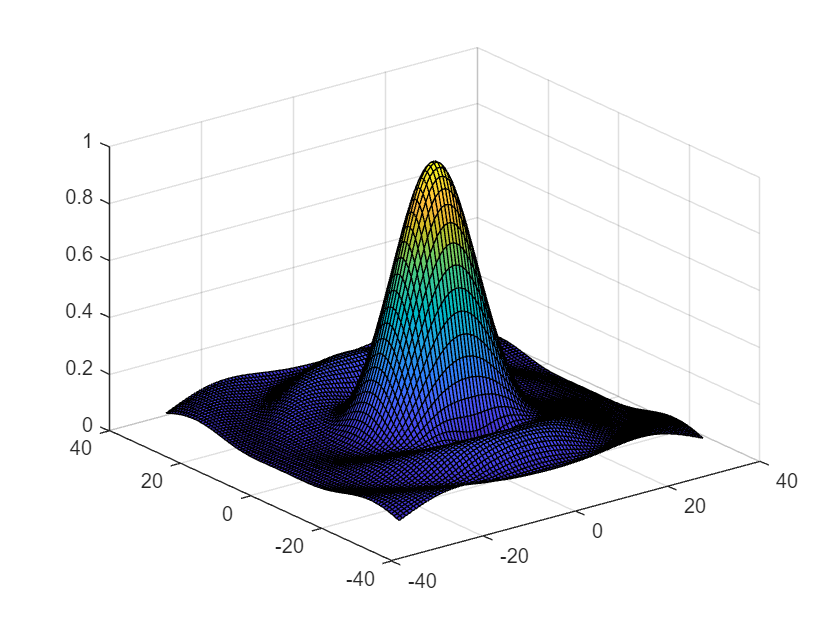

[X4,Y4,E3D_cal4]=Efieldcalculation("3D_input_field_PCL.txt");
figure
surf(X4,Y4,(E3D_cal4/max(max(E3D_cal4))));

function [X,Eoutn] =SFT(Einn_abs,Einn_phase,x,lambda,do,w2)
X=linspace(-w2,w2,4000);
F1=zeros(1,length(X));
for h=1:length(X)
    z=X(h);
    F0=((Einn_abs)).*exp(-1i*Einn_phase).*exp(-1i*pi*(1/lambda)*(1/do)*((z-x).^2));
    F1(h)=trapz(x,F0);
end
Eoutn=F1/max(abs(F1));
end

function [X,Y,E3D_cal]=Efieldcalculation(Input)
INPUT1 = readtable(Input);
DD1=size(INPUT1);
D1=sqrt(DD1(1));
X = reshape(INPUT1.Var1,[D1,D1])';
Y = reshape(INPUT1.Var2,[D1,D1])';
EXR1=reshape(INPUT1.Var4,[D1,D1])';
EXI1=reshape(INPUT1.Var5,[D1,D1])';
EYR1=reshape(INPUT1.Var6,[D1,D1])';
EYI1=reshape(INPUT1.Var7,[D1,D1])';
EZR1=reshape(INPUT1.Var8,[D1,D1])';
EZI1=reshape(INPUT1.Var9,[D1,D1])';
EXM1=sqrt(EXR1.^2+EXI1.^2);
EYM1=sqrt(EYR1.^2+EYI1.^2);
EZM1=sqrt(EZR1.^2+EZI1.^2);
E3D_cal = sqrt(EYM1.^2+EXM1.^2+EZM1.^2);
% E3D_abs1=E3D_abs1/max(max(E3D_abs1));
end